% This Model by Bradley Sutton, PhD, at the University of Illinois,
% modified by Claude Lieber, MD, FGCU
% has been adapted from the MATLAB code presented in Hoppensteadt and Peskin
% "Modeling and Simulation in Medicine and the Life Sciences"
clear
% close all
clc
% Time parameters
T = 0.0125;  % Duration of heartbeat: 0.0125 min = 1 cycle
Ts = 0.4*T;  % Duration of systole: 40% of cycle
dt = .00005*T; % This choice implies 20,000 time steps per cycle
Beats=16*T;    % 16 heart beats displayed per model runtime
% Compliance and resistance parameters. Note that valve resistances are not
% supposed to be realistic, just small enough to be negligible
Csa = .00175;  % Systemic arterial compliance: L/mmHg, original=0.0175
Rs = 17.28;    % Systemic resistance: mmHg/(L/min) - initial value 17.28
Rmi =0.01;     % mitral valve resistance: mmHg/(L/min) - initial value 0.01
RAo =0.01;     % Aortic valve resistance: mmHg/(L/min) - initial value 0.01
AoBkflo=0;    % no regurgitation (S = 0)

Vlvd = .027;   % Left ventricular volume when PLV=0 (Residual volume)
Vsad = .825;   % Systemic arterial volume when Psa = diastolic press.
Pla = 5;       % Left atrial pressure: mmHg Initially 5 mmHg
% Parameters for Clv(t)
CLVD =0.0146;  % Max (diastolic) value of CLV: L/mmHg Initially 0.0146
CLVS = 5e-5;   % Min (systolic) value of CLV: L/mmHg initially 5e-5
tauS = .0025;  % CLV time constant during systole: min (0.0025)
tauD = .005;   % CLV time constant during diastole: min (0.001)
Kd=1.4878;     % Constants found in script for aortic stenosis
Ks=0.0051;
% Initialization parameters
Plvi = 5;      % Initial value of Plv: mmHg
Psai = 80;     % initial value of Psa: mmHg (diastolic blood pressure)
Cycle=T/dt;
Syst=Ts/dt;
Diastole=Cycle-Syst;

% Store normal values before introducing aortic insufficiency
sim('Cardio_SA_LV');
normal_CLVD = CLVD;
normal_CLVS = CLVS;
normal_Pla = Pla;
normal_EDV = VLV(end);
normal_ESV = VLV(end-Diastole+1);
normal_SV = normal_EDV - normal_ESV;
normal_CO = (1/T) * normal_SV;
normal_SV_ml = normal_SV * 1000;
normal_systolic = max(PSA(end-Cycle:end));
normal_diastolic = min(PSA(end-Cycle:end));
normal_pulse_pressure = normal_systolic - normal_diastolic;

fprintf('Normal end-systolic compliance = %0.05f L/mmHg\n\n', CLVS)

Normal end-systolic compliance = 0.00005 L/mmHg



fprintf('Normal end-diastolic compliance = %0.8f L/mmHg\n\n', CLVD)

Normal end-diastolic compliance = 0.01460000 L/mmHg




t=BloodFlows.time;
figure('color','white')
plot(VLV(300000:end),PLV(300000:end),'linewidth',2);
title('Normal Cardiac Cycle - No insufficiency','FontSize',18,'FontWeight','bold')
xlabel('Ventricular Volume - Liters','FontSize',14)
ylabel('Ventricular Pressure - mm Hg','FontSize',14)
axis([0.01 max(VLV)+0.01 0 max(PLV)+10])
hold on

EDV = VLV(end);
ESV = VLV(end-Diastole+1);
SV = EDV-ESV;
HR = 1/T;
CO = HR*SV;
fprintf('Normal Cardiac Output = %1.2f liters/min \n\n', CO)

Normal Cardiac Output = 5.18 liters/min 



SV_ml = 1e3*SV; % converts S.V. from l/beat to ml/beat
fprintf('Normal Stroke Volume = %2.1f ml/beat \n\n', SV_ml)

Normal Stroke Volume = 64.7 ml/beat 




% Work calculation for normal condition
deltaP=diff(PLV(end-Cycle:end-Cycle+Syst));
SumV=(VLV(end-Cycle:end-Cycle+Syst-1)+VLV(end-Cycle+1:end-Cycle+Syst))/2;
W=sum(deltaP.*SumV); % Work in mmHg*L
W=0.1333*W; % converts W from mmHg*L to joules
normal_W = W;
fprintf('Press.*Vol. Work per Stroke (per heartbeat) = %2.4f joules/beat\n\n', W)

Press.*Vol. Work per Stroke (per heartbeat) = 1.1511 joules/beat



fprintf('Press.*Vol. Work per min. = %2.4f joules/min\n\n', HR*W)

Press.*Vol. Work per min. = 92.0914 joules/min



fprintf('Arterial pressure = %3.0f/%3.0f mmHg \n\n', ...
    max(PSA(end-Cycle:end)), min(PSA(end-Cycle:end)))

Arterial pressure = 102/ 75 mmHg 



fprintf('Ventricular pressure = %3.0f/%3.0f mmHg \n\n', ...
     max(PLV(end-Cycle:end)), min(PLV(end-Cycle:end)))

Ventricular pressure = 102/  5 mmHg 




% Simulate model with backflow (aortic insufficiency)
AoBkflo=0.0002; % 1/Resistance to backflow during diastole

% Store values after introducing aortic insufficiency but before compensation
sim('Cardio_SA_LV');
insuff_precomp_CLVD = CLVD;
insuff_precomp_CLVS = CLVS;
insuff_precomp_EDV = VLV(end);
insuff_precomp_ESV = VLV(end-Diastole+1);
insuff_precomp_SV = insuff_precomp_EDV - insuff_precomp_ESV;
insuff_precomp_systolic = max(PSA(end-Cycle:end));
insuff_precomp_diastolic = min(PSA(end-Cycle:end));
insuff_precomp_pulse_pressure = insuff_precomp_systolic - insuff_precomp_diastolic;

% for/loop to calculate compensation of compliance due to extra workload
NewCLVD=0;
NewCLVS=0;
for k=1:10
    CLVD=(NewCLVD+CLVD)/2; % Averages new compliances with old ones
    CLVS=(NewCLVS+CLVS)/2;
    sim('Cardio_SA_LV');
    NewCLVS=Ks/max(PLV(end-Cycle:end)); % Recalculates compliances with new ventricular pressures
    NewCLVD=Kd/max(PLV(end-Cycle:end));
end

% Store values after compliance adjustment but before atrial pressure compensation
compensated_CLVD = CLVD;
compensated_CLVS = CLVS;
compensated_EDV = VLV(end);
compensated_ESV = VLV(end-Diastole+1);
compensated_SV = compensated_EDV - compensated_ESV;

% for/loop to perform atrial pressure compensation
initial_Pla = Pla; % Store initial Pla for comparison
for k=1:20
    Pla=Pla+0.2;
    sim('Cardio_SA_LV');
    SBP=max(PSA(end-Cycle:end));
    if SBP>120
        break
    end
end

% Store values after full compensation
final_CLVD = CLVD;
final_CLVS = CLVS;
final_EDV = VLV(end);
final_ESV = VLV(end-Diastole+1);
final_SV = final_EDV - final_ESV;
final_systolic = max(PSA(end-Cycle:end));
final_diastolic = min(PSA(end-Cycle:end));
final_pulse_pressure = final_systolic - final_diastolic;

% Print results for aortic insufficiency after complete compensation
fprintf('\n        Aortic Insufficiency Analysis\n')


        Aortic Insufficiency Analysis


fprintf('------------------------------------------------------------\n\n')

------------------------------------------------------------




% i. Report the new CLVD and CLVS
fprintf('i. New compliances after compensation:\n')

i. New compliances after compensation:


fprintf('   End-systolic compliance (CLVS) = %0.5f L/mmHg\n', final_CLVS)

   End-systolic compliance (CLVS) = 0.00005 L/mmHg


fprintf('   End-diastolic compliance (CLVD) = %0.4f L/mmHg\n\n', final_CLVD)

   End-diastolic compliance (CLVD) = 0.0156 L/mmHg




% ii. Are they increased or decreased?
fprintf('ii. Compliance changes:\n')

ii. Compliance changes:


if final_CLVD > normal_CLVD
    fprintf('   CLVD is increased\n')
else
    fprintf('   CLVD is decreased\n')
end

   CLVD is increased


if final_CLVS < normal_CLVS
    fprintf('   CLVS is decreased\n\n')
else
    fprintf('   CLVS is increased\n\n')
end

   CLVS is increased




% iii. Explain why they have changed
fprintf('iii. Explanation for changes:\n')

iii. Explanation for changes:


fprintf('    CLVD increased to accommodate the extra volume from regurgitant blood.\n')

    CLVD increased to accommodate the extra volume from regurgitant blood.


fprintf('    This allows the ventricle to handle the increased preload without excessive pressure rise.\n')

    This allows the ventricle to handle the increased preload without excessive pressure rise.


fprintf('    CLVS decreased to reflect increased contractility needed to eject the larger volume.\n')

    CLVS decreased to reflect increased contractility needed to eject the larger volume.


fprintf('    This simulates the ventricle''s attempt to maintain cardiac output despite the regurgitant flow.\n\n')

    This simulates the ventricle's attempt to maintain cardiac output despite the regurgitant flow.




% iv. Has the distance between them changed?
distance_normal = normal_CLVD - normal_CLVS;
distance_final = final_CLVD - final_CLVS;
fprintf('iv. Distance between CLVD and CLVS:\n')

iv. Distance between CLVD and CLVS:


fprintf('    Changed from %0.5f to %0.5f (increased)\n\n', distance_normal, distance_final)

    Changed from 0.01455 to 0.01550 (increased)




% Print final results
fprintf('Final mean atrial pressure = %2.3f mmHg\n\n', Pla)

Final mean atrial pressure = 6.400 mmHg



EDV = VLV(end);
ESV = VLV(end-Diastole+1);
SV = EDV-ESV; % This renders stroke volume as L/beat
HR = 1/T;
CO = HR*SV;
SV_ml = 1e3*SV; % converts S.V. from l/beat to ml/beat
fprintf('Cardiac Output = %1.2f liters/min \n\n', CO)

Cardiac Output = 7.09 liters/min 



fprintf('Stroke Volume = %2.1f ml/beat \n\n', SV_ml)

Stroke Volume = 88.7 ml/beat 




% Calculate work for insufficiency condition
deltaP=diff(PLV(end-Cycle:end-Cycle+Syst));
SumV=(VLV(end-Cycle:end-Cycle+Syst-1)+VLV(end-Cycle+1:end-Cycle+Syst))/2;
W=sum(deltaP.*SumV);
W=0.1333*W; % converts W from mmHg*L to joules
final_W = W;

fprintf('Press.*Vol. Work per Stroke (per heartbeat) = %2.4f joules/beat\n\n', W)

Press.*Vol. Work per Stroke (per heartbeat) = 1.7089 joules/beat



fprintf('Press.*Vol. Work per min. = %2.4f joules/min\n\n', HR*W)

Press.*Vol. Work per min. = 136.7129 joules/min



fprintf('Arterial pressure = %3.0f/%3.0f mmHg \n\n', ...
    max(PSA(end-Cycle:end)), min(PSA(end-Cycle:end)))

Arterial pressure = 122/ 83 mmHg 



fprintf('Ventricular pressure = %3.0f/%3.0f mmHg \n\n', ...
    max(PLV(end-Cycle:end)), min(PLV(end-Cycle:end)))

Ventricular pressure = 122/  6 mmHg 



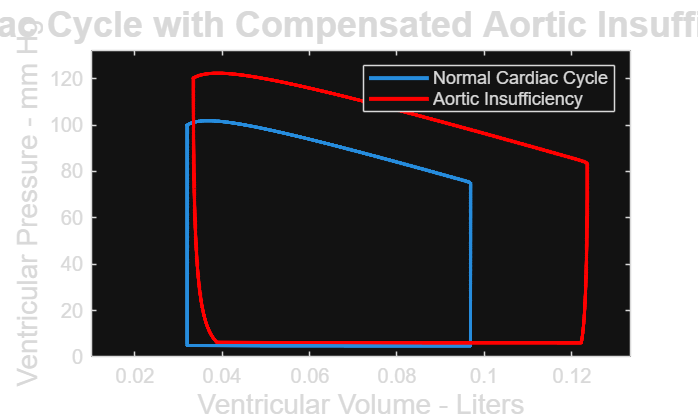


% Plot the compensated cardiac cycle
plot(VLV(300000:end),PLV(300000:end),'linewidth',2, 'Color',"r");
title('Cardiac Cycle with Compensated Aortic Insufficiency','FontSize',18,'FontWeight','bold')
xlabel('Ventricular Volume - Liters','FontSize',14)
ylabel('Ventricular Pressure - mm Hg','FontSize',14)
axis([0.01 max(VLV)+0.01 0 max(PLV)+10])
legend('Normal Cardiac Cycle','Aortic Insufficiency')


% d. Analysis after compensation
fprintf('\n--- ANALYSIS AFTER COMPENSATION ---\n')


--- ANALYSIS AFTER COMPENSATION ---



% ii. Isovolumic contraction period
fprintf('d.ii. The isovolumic contraction period is shorter because:\n')

d.ii. The isovolumic contraction period is shorter because:


fprintf('     The increased preload raises left ventricular pressure more quickly,\n')

     The increased preload raises left ventricular pressure more quickly,


fprintf('     allowing the ventricle to reach aortic pressure faster.\n\n')

     allowing the ventricle to reach aortic pressure faster.




% iii. Isovolumic relaxation period
fprintf('d.iii. The isovolumic relaxation period is shorter because:\n')

d.iii. The isovolumic relaxation period is shorter because:


fprintf('     Rapid filling from regurgitant flow increases ventricular volume and pressure more quickly.\n\n')

     Rapid filling from regurgitant flow increases ventricular volume and pressure more quickly.




% iv. Stroke volume comparison
fprintf('d.iv. Stroke volume comparison:\n')

d.iv. Stroke volume comparison:


fprintf('     Normal stroke volume: %.1f ml/beat\n', normal_SV_ml)

     Normal stroke volume: 64.7 ml/beat


fprintf('     Compensated stroke volume: %.1f ml/beat\n', SV_ml)

     Compensated stroke volume: 88.7 ml/beat


if SV_ml > normal_SV_ml
    fprintf('     The stroke volume has increased to compensate for regurgitant flow.\n\n')
else
    fprintf('     The stroke volume has decreased despite compensation.\n\n')
end

     The stroke volume has increased to compensate for regurgitant flow.




% v. Work done per stroke
fprintf('d.v. Work done per stroke after compensation: %.4f joules/beat\n\n', final_W)

d.v. Work done per stroke after compensation: 1.7089 joules/beat




% vi. Work comparison
fprintf('d.vi. Work comparison:\n')

d.vi. Work comparison:


fprintf('     Normal work: %.4f joules/beat\n', normal_W)

     Normal work: 1.1511 joules/beat


fprintf('     Compensated work: %.4f joules/beat\n', final_W)

     Compensated work: 1.7089 joules/beat


fprintf('     The work increased by %.4f joules/beat (%.1f%%)\n\n', ...
    final_W-normal_W, ((final_W-normal_W)/normal_W)*100)

     The work increased by 0.5578 joules/beat (48.5%)



fprintf('     This increase is due to:\n')

     This increase is due to:


fprintf('     1. Larger volume of blood being ejected (increased preload)\n')

     1. Larger volume of blood being ejected (increased preload)


fprintf('     2. Increased contractility needed to overcome regurgitant flow\n')

     2. Increased contractility needed to overcome regurgitant flow


fprintf('     3. Higher pressures needed to maintain cardiac output\n\n')

     3. Higher pressures needed to maintain cardiac output




% vii. Aortic blood pressure changes
fprintf('d.vii. Aortic blood pressure changes:\n')

d.vii. Aortic blood pressure changes:


fprintf('      Normal: %3.0f/%3.0f mmHg\n', normal_systolic, normal_diastolic)

      Normal: 102/ 75 mmHg


fprintf('      Compensated: %3.0f/%3.0f mmHg\n\n', final_systolic, final_diastolic)

      Compensated: 122/ 83 mmHg



if final_systolic > normal_systolic
    fprintf('      Systolic pressure increased due to:\n')
    fprintf('      - Increased stroke volume\n')
    fprintf('      - More forceful ventricular contraction\n\n')
else
    fprintf('      Systolic pressure decreased or unchanged\n\n')
end

      Systolic pressure increased due to:


      - Increased stroke volume


      - More forceful ventricular contraction



if final_diastolic < normal_diastolic
    fprintf('      Diastolic pressure decreased due to:\n')
    fprintf('      - Regurgitant flow during diastole\n')
    fprintf('      - Reduced forward flow to periphery\n\n')
elseif final_diastolic > normal_diastolic
    fprintf('      Diastolic pressure increased due to:\n')
    fprintf('      - Compensatory mechanisms overcoming regurgitant effects\n')
    fprintf('      - Increased atrial pressure and preload\n\n')
else
    fprintf('      Diastolic pressure unchanged\n\n')
end

      Diastolic pressure increased due to:


      - Compensatory mechanisms overcoming regurgitant effects


      - Increased atrial pressure and preload




% viii. Pulse pressure changes
fprintf('d.viii. Pulse pressure changes:\n')

d.viii. Pulse pressure changes:


fprintf('       Normal pulse pressure: %d mmHg\n', normal_pulse_pressure)

       Normal pulse pressure: 2.724554e+01 mmHg


fprintf('       Compensated pulse pressure: %d mmHg\n', final_pulse_pressure)

       Compensated pulse pressure: 3.930307e+01 mmHg


if final_pulse_pressure > normal_pulse_pressure
    fprintf('       Pulse pressure increased by %d mmHg due to:\n', ...
        final_pulse_pressure - normal_pulse_pressure)
    fprintf('       - Higher systolic pressure from increased stroke volume\n')
    fprintf('       - Lower diastolic pressure from regurgitant flow\n\n')
else
    fprintf('       Pulse pressure unchanged or decreased\n\n')
end

       Pulse pressure increased by 1.205753e+01 mmHg due to:


       - Higher systolic pressure from increased stroke volume


       - Lower diastolic pressure from regurgitant flow




% ix. Stroke volume difference without compensation
uncompensated_SV_ml = (insuff_precomp_EDV - insuff_precomp_ESV) * 1000;
fprintf('d.ix. Stroke volume without compensation:\n')

d.ix. Stroke volume without compensation:


fprintf('      Normal: %.1f ml/beat\n', normal_SV_ml)

      Normal: 64.7 ml/beat


fprintf('      With AI (uncompensated): %.1f ml/beat\n', uncompensated_SV_ml)

      With AI (uncompensated): 65.5 ml/beat


fprintf('      Difference: %.1f ml/beat\n\n', normal_SV_ml - uncompensated_SV_ml)

      Difference: -0.7 ml/beat




% x. Diastolic arterial blood pressure - Energy explanation
fprintf('d.x. Diastolic arterial blood pressure - Energy explanation:\n')

d.x. Diastolic arterial blood pressure - Energy explanation:


fprintf('     In aortic insufficiency:\n')

     In aortic insufficiency:


fprintf('     1. During systole: Increased potential energy stored in arterial walls\n')

     1. During systole: Increased potential energy stored in arterial walls


fprintf('        (higher systolic pressure due to increased stroke volume)\n')

        (higher systolic pressure due to increased stroke volume)


fprintf('     2. During diastole: Potential energy is lost as kinetic energy of regurgitant flow\n')

     2. During diastole: Potential energy is lost as kinetic energy of regurgitant flow


fprintf('        (blood flows backward into ventricle instead of maintaining arterial pressure)\n')

        (blood flows backward into ventricle instead of maintaining arterial pressure)


fprintf('     3. Net effect: Less energy remains in the system to maintain diastolic pressure\n')

     3. Net effect: Less energy remains in the system to maintain diastolic pressure


fprintf('     4. The decreased diastolic pressure reflects this energy loss\n\n')

     4. The decreased diastolic pressure reflects this energy loss



if final_diastolic > normal_diastolic
    fprintf('     Note: In this model, compensatory mechanisms (increased atrial pressure)\n')
    fprintf('     have raised the diastolic pressure above normal, which is not typical clinically.\n')
    fprintf('     This suggests the model''s compensation may be overestimating certain effects.\n\n')
end

     Note: In this model, compensatory mechanisms (increased atrial pressure)


     have raised the diastolic pressure above normal, which is not typical clinically.


     This suggests the model's compensation may be overestimating certain effects.




% xi. Water hammer pulse and Quincke's pulse sign
fprintf('d.xi. Water Hammer Pulse and Quincke''s Pulse Sign:\n')

d.xi. Water Hammer Pulse and Quincke's Pulse Sign:


fprintf('      Water Hammer Pulse (Corrigan''s Pulse):\n')

      Water Hammer Pulse (Corrigan's Pulse):


fprintf('      - Characterized by a rapid rise and fall in arterial pressure\n')

      - Characterized by a rapid rise and fall in arterial pressure


fprintf('      - In the model, this corresponds to the rapid increase in aortic flow during systole\n')

      - In the model, this corresponds to the rapid increase in aortic flow during systole


fprintf('        followed by negative flow during diastole (regurgitation)\n')

        followed by negative flow during diastole (regurgitation)


fprintf('      - This creates the bounding pulse felt in peripheral arteries\n\n')

      - This creates the bounding pulse felt in peripheral arteries




fprintf('      Quincke''s Pulse Sign:\n')

      Quincke's Pulse Sign:


fprintf('      - Visible pulsations in capillary beds (e.g., fingernails)\n')

      - Visible pulsations in capillary beds (e.g., fingernails)


fprintf('      - Caused by the wide pulse pressure and rapid pressure oscillations\n')

      - Caused by the wide pulse pressure and rapid pressure oscillations


fprintf('      - In the model, this corresponds to the large oscillations in aortic flow\n')

      - In the model, this corresponds to the large oscillations in aortic flow


fprintf('        between positive (systole) and negative (diastole) values\n\n')

        between positive (systole) and negative (diastole) values



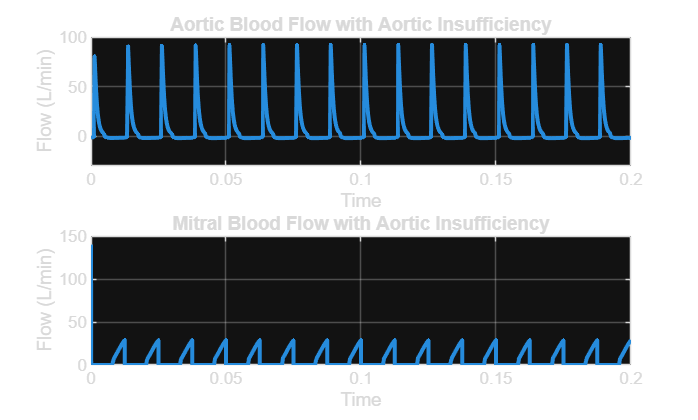


% Create plots for aortic and ventricular blood flows
figure('color','white')
subplot(2,1,1)
plot(t, BloodFlows.signals.values(:,2), 'linewidth', 2)
title('Aortic Blood Flow with Aortic Insufficiency')
xlabel('Time')
ylabel('Flow (L/min)')
ylim([-30 100]) % Extend y-axis to show negative values
grid on

subplot(2,1,2)
plot(t, BloodFlows.signals.values(:,1), 'linewidth', 2)
title('Mitral Blood Flow with Aortic Insufficiency')
xlabel('Time')
ylabel('Flow (L/min)')
grid on


% xii. Explanation of negative flows in aortic blood flow
fprintf('d.xii. Negative flows in aortic blood flow graph:\n')

d.xii. Negative flows in aortic blood flow graph:


fprintf('       The negative flows represent regurgitant flow during diastole, which occurs because:\n')

       The negative flows represent regurgitant flow during diastole, which occurs because:


fprintf('       1. The aortic valve cannot close completely due to insufficiency\n')

       1. The aortic valve cannot close completely due to insufficiency


fprintf('       2. During diastole, left ventricular pressure < aortic pressure\n')

       2. During diastole, left ventricular pressure < aortic pressure


fprintf('       3. Blood flows backward from the aorta into the left ventricle\n')

       3. Blood flows backward from the aorta into the left ventricle


fprintf('       4. This regurgitant flow reduces effective forward flow to the periphery\n')

       4. This regurgitant flow reduces effective forward flow to the periphery


fprintf('       5. It contributes to the decreased diastolic pressure and wide pulse pressure\n')

       5. It contributes to the decreased diastolic pressure and wide pulse pressure


fprintf('       6. Clinically, this manifests as the water hammer pulse and Quincke''s pulse\n\n')

       6. Clinically, this manifests as the water hammer pulse and Quincke's pulse

